# Projekt 5

## Nastavitev parametrov

% Definicija parametrov
T = 0.01;
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

## Statična karaktersitika

% Inicializacija parametrov
numSteps = N;
stepSize = 0.05;
inputValues = 0:stepSize:2;  % Vrednosti vhodnega signala
outputValues = zeros(size(inputValues));  % Inicializacija vektorja za rezultate

% Glavna zanka za različne vrednosti vhodnega signala
for index = 1:length(inputValues)
    currentInput = inputValues(index);  % Trenutna vrednost vhodnega signala
    u = currentInput * ones(numSteps, 1);  % Vhodni signal (vektor enakih vrednosti)

    % Inicializacija stanja sistema
    state = [0, 0];

    % Inicializacija izhodnega vektorja
    outputSignal = zeros(numSteps, 1);

    % Simulacija sistema
    for step = 1:numSteps
        % Klic funkcije sistema
        [position, velocity] = helicrane(u(step), state);

        % Posodobitev stanja
        state = [velocity, position];

        % Shranjevanje trenutnega izhoda
        outputSignal(step) = position;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    steadyStateOutput = mean(outputSignal(100:end));

    % Shranjevanje rezultata v outputValues
    outputValues(index) = steadyStateOutput;
end

% Risanje rezultata
figure;
plot(inputValues, outputValues);
title("Statična karakteristika sistema");
xlabel("Vhodni signal [V]");
ylabel("Izhodni signal [V]");



## Generiranje in risanje APRBS signala

% Parametri
N = 3000; % Število vzorcev
Th = 0.2; % Časovna konstanta
amplitude_train = 2.5;
amplitude_test = 2.0;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri testu more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

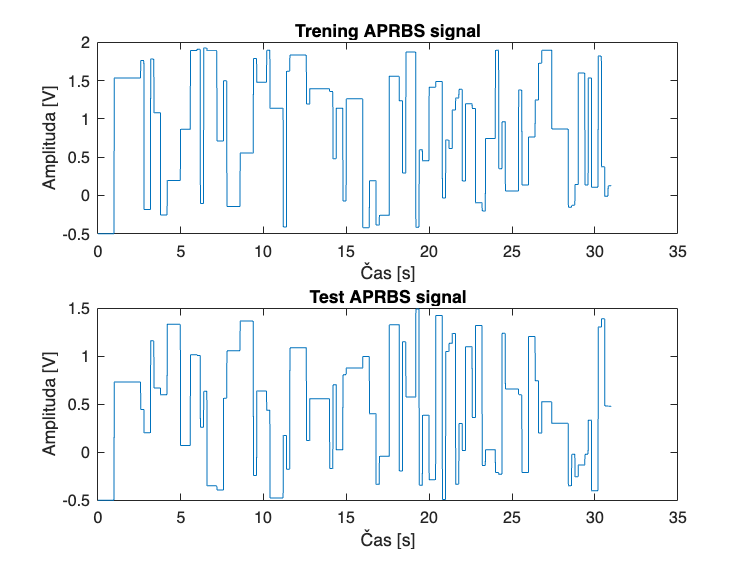

d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri train more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

## odziv sistema na vhodni signal

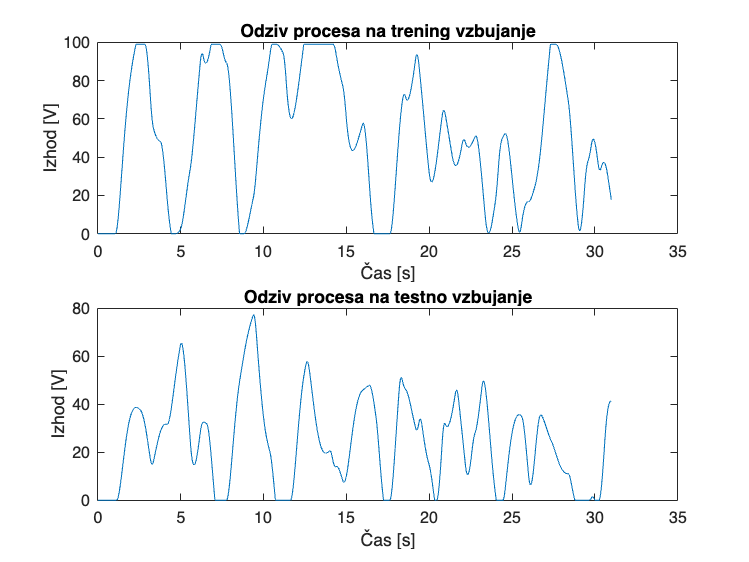


% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

% 
% % Preverjanje dolžine vektorjev u_train in y_train
% if length(u_train) > 2 && length(y_train) > 2
%     % Priprava vhodnih in izhodnih podatkov za učenje
%     X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
%     Y_train_podatki = y_train(3:end);
% 
%     % Premešanje podatkov za učenje
%     perm_indeksi = randperm(size(X_train_podatki, 1));
%     X_train_premesani = X_train_podatki(perm_indeksi, :);
%     Y_train_premesani = Y_train_podatki(perm_indeksi, :);
% 
%     % Priprava vhodnih in izhodnih podatkov za testiranje
%     X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
%     Y_test_podatki = y_test(3:end);
% 
%     % Simulacija helicrana brez uporabe funkcije
%     % Inicializacija stanja
%     zacetno_stanje = [0, 0];
% 
%     % Dolžina vhoda
%     N = length(u_train); % Tu mora biti dolžina u_train
% 
%     % Inicializacija izhoda
%     izhodi = zeros(N, 1);
% 
%     % Glavna zanka za simulacijo
%     for i = 1:N
%         % Klic funkcije helicrane
%         [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);
% 
%         % Posodobitev stanja
%         zacetno_stanje = [fip_, fi_];
% 
%         % Shranjevanje izhoda
%         izhodi(i) = fi_;
%     end
% 
%     % Prikaz končnih izhodov (izhodi)
%     disp(izhodi);
% else
%     disp('Napaka: u_train ali y_train nimata dovolj elementov.');
% end

## nevronska mreža

net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;
[net, ~] = train(net, X_train_podatki', Y_train_podatki');

% Napovedovanje na trening množici
Y_pred_train = net(X_train_podatki');

% Napovedovanje na testni množici
Y_pred_test = net(X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
title("Modeliranje trening množice z NN");
hold on;
plot(Y_pred_train);
xlabel("Vzorec");
ylabel("Odziv [V]");

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN");
hold on;
plot(Y_pred_test);
xlabel("Vzorec");
ylabel("Odziv [V]");


## Takagi Sugeno model

% Adjusted Takagi Sugeno model

% 1) Prepare input (X_train) and output (Y_train) data
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);

% [X_train_podatki, mu_X_train, sigma_X_train] = normalize(X_train_podatki);
% [Y_train_podatki, mu_Y_train, sigma_Y_train] = normalize(Y_train_podatki);
perm = randperm(size(X_train_podatki, 1))

perm =         1818         453        2213        2718         296        1426        1361        2357        1680        2974        2734        2358        1359        2604        1307        2324        1871        3025        2924         292        1383        2982         716        1685        2424        1677        1449         947        2417         616        1487        1217         590        2685        3042        2407        2036        3093        2543          18         177        1282        2250        1636         479        2028        2723         898        1191        1060


X_train_podatki = X_train_podatki(perm, :);
Y_train_podatki = Y_train_podatki(perm, :);

% Prepare the test data with the same normalization parameters
X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
%X_test_podatki = (X_test_podatki - mu_X_train) ./ sigma_X_train; % Normalize using training parameters
Y_test_podatki = y_test(3:end);


% Adjusted model parameters
R = 13; % Number of rules
n = size(X_train_podatki', 1); % Number of data points
N = size(X_train_podatki', 2); % Dimensions of data


% Initialize parameters
C = rand(R, 2); % Centers of the fuzzy rules
O = [20, 20] + rand(R, 2); % Spreads of the fuzzy rules
W = 4 * rand(R, n) - 2; % Weights for the linear models
b = 4 * rand(R, 1) - 2; % Biases for the linear models


[C, O, W, b, e] = TS_train(C, O, W, b, X_train_podatki', Y_train_podatki', 0.000002, 500);

Epoch 1: Error: 800.701950
Epoch 101: Error: 0.743357
Epoch 201: Error: 0.683150
Epoch 301: Error: 0.642343
Epoch 401: Error: 0.612647
Final error: 0.589687


% Prediction on training and test data
Y_pred_train = TS_eval(C, O, W, b, X_train_podatki');
Y_pred_test = TS_eval(C, O, W, b, X_test_podatki');

% Denormalization of predictions
% Y_pred_train = (Y_pred_train * sigma_Y_train) + mu_Y_train;
% Y_pred_test = (Y_pred_test * sigma_Y_train) + mu_Y_train;


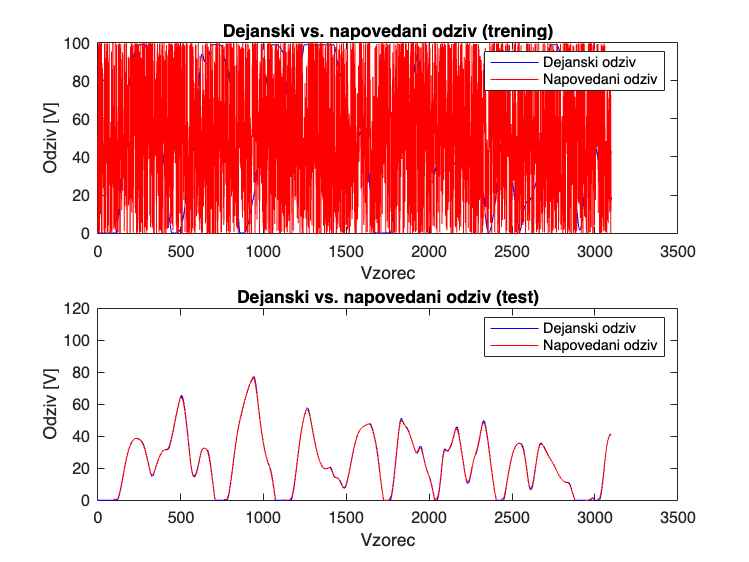

% Plotting results
figure;
subplot(2, 1, 1);
plot(y_train, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_train, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show'); % Prikaže legendo

% Test data plot with modified y-axis limits
subplot(2, 1, 2);
plot(y_test, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_test, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show'); % Display legend
ylim([0 120]); % Set custom y-axis limits for the test plot

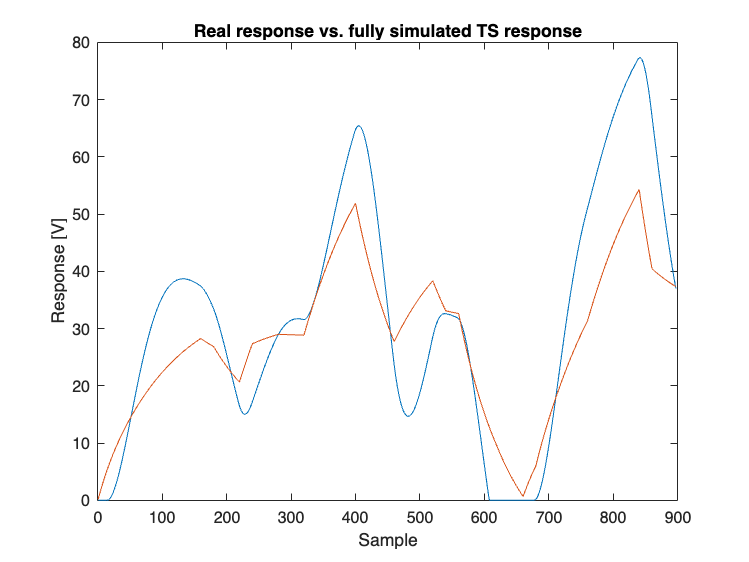

% Fully simulated response
X_sim = X_test_podatki(100, :);
Y_sim = [];

for i = 102:998
    y = TS_eval(C, O, W, b, X_sim');
    Y_sim = [Y_sim, y];
    X_sim = [u_test(i), u_test(i-1), -y, X_sim(3)]; 
end

figure;
plot(y_test(102:998));
title("Real response vs. fully simulated TS response");
hold on;
plot(Y_sim);
xlabel("Sample");
ylabel("Response [V]");


% Save results
save('model_luka.mat', 'C', 'O', 'W', 'b');

% Function to train the Takagi-Sugeno fuzzy model
function [C, O, W, b, e_avg] = TS_train(C, O, W, b, X, Y, alpha, epochs)
    % X - matrix
    % Y - row vector
    for i = 1:epochs
        e_avg = 0;
        for j = 1:size(X, 2)
            [C, O, W, b, e] = TS_train_single(C, O, W, b, X(:, j), Y(j), alpha);
            e_avg = e_avg + e;
        end
        e_avg = e_avg / size(X, 2);
        
        if mod(i, 100) == 1
            fprintf("Epoch %d: Error: %f\n", i, e_avg);
        end
    end
    fprintf("Final error: %f\n", e_avg);
end

% Function to train a single data point
function [C, O, W, b, e] = TS_train_single(C, O, W, b, X, Y, alpha)
    % TS_TRAIN training function for the TS model
    % C: matrix of centers RxN
    % O: matrix of standard deviations RxN
    % W: matrix of weights 
    % b: matrix of biases
    % X: train input matrix - column vector
    % Y: train output matrix - scalar
    % alpha: learning rate - scalar

    mu = exp(-0.5 * sum((X(3:4)' - C).^2 ./ (O.^2), 2)); % mu - column vector

    % Prevent division by very small numbers
    if sum(mu) < 1e-6
        mu = mu + 1e-6;
    end

    % Normalize the membership values
    mu = mu / sum(mu);

    % Calculate the output for the current input
    s = W * X + b;
    y = sum(mu .* s);

    % Compute the error
    e = (Y - y)^2;

    % Compute gradients
    dmu_dC = (X(3:4)' - C) ./ (O.^2) .* mu;
    dmu_dO = (X(3:4)' - C).^2 ./ (O.^3) .* mu;

    dy_dC = dmu_dC .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    dy_dO = dmu_dO .* (s - sum(s .* mu)) ./ (sum(mu).^2);

    dy_db = mu;
    dy_dW = mu * X';

    de_dC = -2 * (Y - y) * dy_dC;
    de_dO = -2 * (Y - y) * dy_dO;
    de_db = -2 * (Y - y) * dy_db;
    de_dW = -2 * (Y - y) * dy_dW;

    % Update the parameters
    C = C - alpha .* de_dC;
    O = O - alpha .* de_dO;
    b = b - alpha .* de_db;
    W = W - alpha .* de_dW;
end

% Function to evaluate the Takagi-Sugeno fuzzy model
function [Y] = TS_eval(C, O, W, b, X)
    N = size(X, 2);
    Y = zeros(1, N);

    for i = 1:N
        mu = exp(-0.5 * sum((X(3:4, i)' - C).^2 ./ (O.^2), 2));
        mu = mu / sum(mu);
        s = W * X(:, i) + b;
        Y(i) = sum(mu .* s);
    end
end

% Function to normalize data
function [X_norm, mu, sigma] = normalize(X)
    mu = mean(X, 1);
    sigma = std(X, 0, 1);
    X_norm = (X - mu) ./ sigma;
end